

close all;

G = tf(8,[1 10 31 30])% Enter the transfer function of the plant here

G =
 
             8
  ------------------------
  s^3 + 10 s^2 + 31 s + 30
 
Continuous-time transfer function.



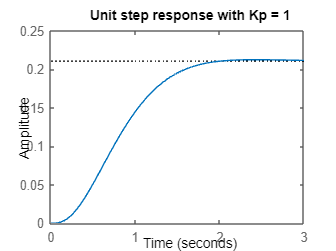


K_p = 1; % Controller with only P configuration
name = sprintf( 'Unit step response with Kp = 1' );
plotCLTF( K_p, G, name ); % Unit step response of the CLTF with K_p as a P-only controller




 K_p2 = 20 % Enter a new value of your choice for the P Controller 

K_p2 = 20

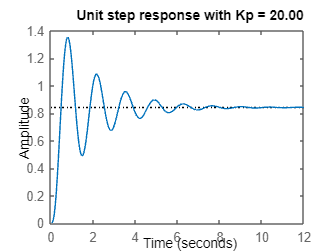

 name = sprintf( 'Unit step response with Kp = %.2f', K_p2 );
 plotCLTF( K_p2, G, name ); % Unit step response of the CLTF with K_p as a P-only controller

% having a larger P figure increases the steady state but also 
% makes a larger overshoot to an unacceptable level.
% due to this overshoot it takes longer to settle.


K_u = 10.5 % change the K value with the one obtained via calculations

K_u = 10.5000

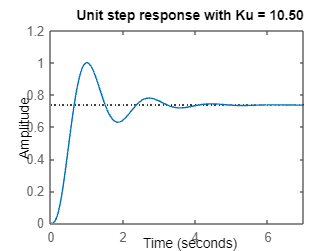

name = sprintf( 'Unit step response with Ku = %.2f', K_u );
plotCLTF( K_u, G, name ); % Unit step response of the CLTF with K as Ultimate Gain



K_1 = 6.176% K1 value here 

K_1 = 6.1760

T_i = 0.86% Ti value here

T_i = 0.8600

T_d =0.215 % Td value here

T_d = 0.2150

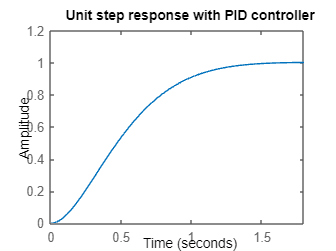

 K_PID = K_1 * (1 + tf( 1, [T_i 0] ) + tf( [T_d 0], 1 ) ); % Update controller with  new PID configuration
 name = sprintf( 'Unit step response with PID controller' );
 plotCLTF( K_PID, G, name ); % Unit step response of the CLTF with K as PID controller


 % the system is the balance of all with a quick enough responce to a steady
% state of 1, with no overshoots allowing the system to run efficiently